# Team Atlas: AI-Powered Seizure Early-Warning System

National Neuroscience Technology Hackathon 2026, Theme C: AI and Brain Data. This live script runs from top to bottom. It loads the saved patient data and the final model, recomputes the headline results, and shows the figures. Every number in the written text comes from the code below. Run all sections once and save, so the outputs are stored in the file.

## 1. Summary

Epilepsy is under-diagnosed where neurologists are scarce, and reading hours of EEG by hand is slow. We built a MATLAB pipeline that detects seizures in scalp EEG from children and young adults and flags them for a clinician to review. It is designed for noisy, low-cost recordings.

What we claim: seizure detection as an early-warning and screening aid. We do not claim to predict seizures before they start, and every alert is meant to be checked by a clinician on the raw EEG.

How it works: raw EEG is filtered and cut into 5-second windows. Each window becomes 126 numbers (band power, line length and spectral entropy for 18 channels), rescaled within each patient. A Random Forest turns them into a risk score from 0 to 1, and an alert fires when the risk stays at or above 0.4 for 3 windows in a row.

## 2. Setup

The code lives in the repository. The data lives outside Git, in the folder named by the ATLAS_DATA environment variable.

if isempty(which('config'))
    here = fileparts(mfilename('fullpath'));
    addpath(genpath(fileparts(here)));
end
cfg = config();
rng(42);

% Switches. Leave them false to use the saved results; set true to recompute (slow).
recomputeModelComparison = false;
rerunRobustness = false;

assert(isfolder(cfg.dataRoot), 'Data folder not found: %s. Set ATLAS_DATA first.', cfg.dataRoot);
assert(license('test', 'Signal_Toolbox') && license('test', 'Statistics_Toolbox'), ...
    'The Signal Processing and Statistics and Machine Learning Toolboxes are required.');
assert(~isempty(cfg.alertThreshold) && cfg.normalizeFeatures, ...
    'config.m must have the locked threshold and normalizeFeatures = true.');
fprintf('Alert threshold %.2f, %d windows in a row, windows of %d s every %.1f s.\n', ...
    cfg.alertThreshold, cfg.alertConsecutiveWindows, cfg.windowSec, cfg.stepSec);

Alert threshold 0.40, 3 windows in a row, windows of 5 s every 2.5 s.


## 3. Data and patients

We use the CHB-MIT Scalp EEG database: pediatric recordings (ages 1.5 to 22) with the start and end of every seizure annotated. Patients were split before any modelling. The two test patients were never used for training, tuning or choosing the threshold.

patients = table(["chb05"; "chb14"; "chb01"; "chb15"; "chb03"; "chb18"], ...
    [7; 9; 11; 16; 14; 18], ...
    ["train"; "train"; "train"; "train"; "test"; "test"], ...
    'VariableNames', {'Patient', 'AgeYears', 'Role'});
disp(patients)

    Patient    AgeYears     Role  
    _______    ________    _______

    "chb05"        7       "train"
    "chb14"        9       "train"
    "chb01"       11       "train"
    "chb15"       16       "train"
    "chb03"       14       "test" 
    "chb18"       18       "test" 



% chb21 is the same person as chb01 and is never used.

## 4. What the signal looks like

Each recording has 18 channels sampled at 256 Hz. After band-pass filtering (0.5 to 40 Hz) it is cut into 5-second windows. Below: one window during a seizure and one seizure-free window from the same patient (chb05), for 4 of the 18 channels.

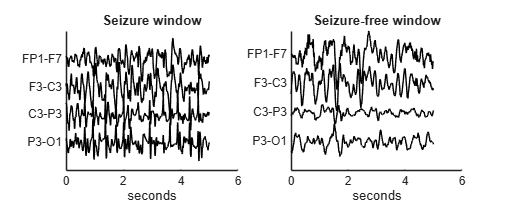

pm = matfile(fullfile(cfg.processedDir, 'chb05.mat'));
labels05 = pm.labels;
file05 = pm.fileName;
szIdx = find(labels05 == 1);
iSz = szIdx(10);
iNo = find(labels05 == 0 & file05 == "chb05_06.edf", 1);
showCh = find(ismember(cfg.channelNames, {'FP1-F7', 'F3-C3', 'C3-P3', 'P3-O1'}));
tt = (0:cfg.windowSamples - 1) / cfg.fs;
figure('Position', [100 100 1000 420]);
tiledlayout(1, 2, 'TileSpacing', 'compact');
titles = {'Seizure window', 'Seizure-free window'};
idxs = [iSz, iNo];
for p = 1:2
    nexttile;  hold on
    w = double(squeeze(pm.windows(idxs(p), :, :)));   % read all channels, then pick four
    w = w(showCh, :);
    sc = 4 * median(std(w, 0, 2));
    for c = 1:numel(showCh)
        plot(tt, (w(c, :) - mean(w(c, :))) + (numel(showCh) + 1 - c) * sc, 'k');
    end
    yticks((1:numel(showCh)) * sc);
    yticklabels(flip(cfg.channelNames(showCh)));
    xlabel('seconds');  title(titles{p});  box off
end

## 5. Features

Each window becomes one row of 126 features: for every channel, the relative power in five brain-wave bands (delta, theta, alpha, beta, gamma), the log line length (how jagged the signal is) and the spectral entropy. Each feature is then rescaled within the patient, using that patient's own median and spread. This needs no labels.

T05 = load(fullfile(cfg.dataRoot, 'features', 'chb05.mat'), 'T').T;
fprintf('chb05: %d windows, %d seizure windows, %d feature columns\n', ...
    height(T05), sum(T05.label), width(T05) - 4);

chb05: 2467 windows, 224 seizure windows, 126 feature columns


T05(1:5, [1:4 5 6 20 41 62])

ans = 5×9 table
    patientID       fileName       windowStartSec    label    delta_FP1F7    delta_F7T7    delta_P8O2    alpha_FP1F7    beta_P7O1
    _________    ______________    ______________    _____    ___________    __________    __________    ___________    _________

     "chb05"     "chb05_01.edf"         17.5           0        0.76753       0.81424       0.74855       0.0091626     0.0093181
     "chb05"     "chb05_01.edf"         22.5           0         0.8995       0.90808       0.72214       0.0078597     0.0067619
     "chb05"     "chb05_01.edf"         27.5           0        0.78351       0.84732       0.73471        0.029499     0.0039169
     "chb05"     "chb05_01.

## 6. Choosing the model

Models were compared with leave-one-patient-out testing on the four training patients: train on three, score the fourth, repeat. The model never sees the patient it is scored on. AUC 0.5 is guessing and 1.0 is perfect. Rescaling every feature within each patient was the key step: without it chb01 was ranked backwards (AUC 0.24).

if recomputeModelComparison
    compareModels();
    testNormalization();
end
modelTbl = table( ...
    ["Raw features, first settings"; "Raw features, tuned forest"; "Raw features, SVM"; "Rescaled within patient (final)"], ...
    [0.807; 0.828; 0.715; 0.992], [0.791; 0.784; 0.766; 0.757], ...
    [0.240; 0.274; 0.515; 0.938], [0.549; 0.603; 0.471; 0.872], ...
    'VariableNames', {'Model', 'chb05', 'chb14', 'chb01', 'chb15'});
modelTbl.Mean = mean(modelTbl{:, 2:5}, 2);
disp(modelTbl)

                  Model                  chb05    chb14    chb01    chb15     Mean  
    _________________________________    _____    _____    _____    _____    _______

    "Raw features, first settings"       0.807    0.791     0.24    0.549    0.59675
    "Raw features, tuned forest"         0.828    0.784    0.274    0.603    0.62225
    "Raw features, SVM"                  0.715    0.766    0.515    0.471    0.61675
    "Rescaled within patient (final)"    0.992    0.757    0.938    0.872    0.88975



% These values come from our saved runs of compareModels, tuneRandomForest and
% testNormalization (set recomputeModelComparison = true to repeat them).

## 7. Choosing the alert threshold

Training patients keep only some of their seizure-free windows, so they cannot show false alarms. We rebuilt two training patients (chb05 and chb01) with every window kept and scored them with models trained on the other patients. The threshold of 0.4 gives about one false alarm per hour while still detecting two thirds of their seizures.

thrTbl = table([0.20; 0.30; 0.40; 0.50], ["12 of 12"; "10 of 12"; "8 of 12"; "6 of 12"], ...
    [15.1; 4.4; 0.46; 0.18], [8.0; 6.1; 1.71; 0.73], ...
    'VariableNames', {'Threshold', 'SeizuresDetected', 'FalseAlarmsPerHour_chb05', 'FalseAlarmsPerHour_chb01'});
disp(thrTbl)

    Threshold    SeizuresDetected    FalseAlarmsPerHour_chb05    FalseAlarmsPerHour_chb01
    _________    ________________    ________________________    ________________________

       0.2          "12 of 12"                 15.1                           8          
       0.3          "10 of 12"                  4.4                         6.1          
       0.4          "8 of 12"                  0.46                        1.71          
       0.5          "6 of 12"                  0.18                        0.73          



## 8. Final test on two unseen patients

The test patients (chb03 and chb18) were scored once with the model and threshold locked beforehand. Their recordings are complete, so false alarms per hour is valid.

loaded = load(fullfile(cfg.dataRoot, 'models', 'rf_final.mat'), 'model');
model = loaded.model;
assert(model.normalize, 'The final model must use per-patient rescaling.');
ids = cfg.testPatients;
Fs = struct();  Rk = struct();  Ev = struct();
nSz = zeros(numel(ids), 1);  nDet = nSz;  nFA = nSz;  hrs = nSz;  aucs = nSz;
allLat = [];
for i = 1:numel(ids)
    id = ids{i};
    T = load(fullfile(cfg.dataRoot, 'features', [id '.mat']), 'T').T;
    risk = predictRisk(model, T);
    [~, ~, ~, aucs(i)] = perfcurve(T.label, risk, 1);
    ev = evaluateEvents(risk, T.label, T.windowStartSec, T.fileName, ...
                        struct('threshold', cfg.alertThreshold));
    nSz(i) = ev.nSeizures;  nDet(i) = ev.nDetected;
    nFA(i) = ev.falseAlarms;  hrs(i) = ev.hoursSeizureFree;
    allLat = [allLat; ev.seizures.latencySec]; %#ok<AGROW>
    Fs.(id) = T;  Rk.(id) = risk;  Ev.(id) = ev;
end
finalTbl = table([string(ids(:)); "Combined"], [nDet; sum(nDet)], [nSz; sum(nSz)], ...
    [nDet ./ nSz; sum(nDet) / sum(nSz)], [nFA; sum(nFA)], [hrs; sum(hrs)], ...
    [nFA ./ hrs; sum(nFA) / sum(hrs)], ...
    [arrayfun(@(i) Ev.(ids{i}).medianLatencySec, 1:numel(ids))'; median(allLat, 'omitnan')], ...
    [aucs; NaN], ...
    'VariableNames', {'Patient', 'Detected', 'Seizures', 'Sensitivity', 'FalseAlarms', ...
                      'HoursNormal', 'FalseAlarmsPerHour', 'MedianLatencySec', 'AUC'});
disp(finalTbl)

     Patient      Detected    Seizures    Sensitivity    FalseAlarms    HoursNormal    FalseAlarmsPerHour    MedianLatencySec      AUC  
    __________    ________    ________    ___________    ___________    ___________    __________________    ________________    _______

    "chb03"           7           7               1           37          16.882             2.1917                 25           0.98371
    "chb18"           5           6         0.83333           77          15.542             4.9544                 15            0.9261
    "Combined"       12          13         0.92308          114          32.424              3.516                 25               NaN



fprintf('Detected %d of %d seizures, %.1f false alarms per hour, median delay %.0f s.\n', ...
    sum(nDet), sum(nSz), sum(nFA) / sum(hrs), median(allLat, 'omitnan'));

Detected 12 of 13 seizures, 3.5 false alarms per hour, median delay 25 s.


## 9. Each seizure and each alert

For every annotated seizure: was it detected, and how many seconds after onset?

for i = 1:numel(ids)
    fprintf('\n%s\n', ids{i});
    disp(Ev.(ids{i}).seizures)
end


chb03


         file         onsetSec    offsetSec    detected    latencySec
    ______________    ________    _________    ________    __________

    "chb03_01.edf"        360         415       true            35   
    "chb03_02.edf"        730       797.5       true          37.5   
    "chb03_03.edf"        430       502.5       true            10   
    "chb03_04.edf"       2160        2215       true          32.5   
    "chb03_34.edf"       1980        2030       true          22.5   
    "chb03_35.edf"       2590      2657.5       true            25   
    "chb03_36.edf"     1722.5        1780       true            25   




chb18


         file         onsetSec    offsetSec    detected    latencySec
    ______________    ________    _________    ________    __________

    "chb18_29.edf"       3475      3527.5       true            25   
    "chb18_30.edf"        540       572.5       false          NaN   
    "chb18_31.edf"       2085      2157.5       true            15   
    "chb18_32.edf"     1907.5        1965       true          12.5   
    "chb18_35.edf"       2195        2265       true            25   
    "chb18_36.edf"      462.5         510       true          12.5   



## 10. What the risk score looks like

One recording from each test patient. Shaded: annotated seizure. Triangles: alerts. Alerts outside the shaded area are false alarms.

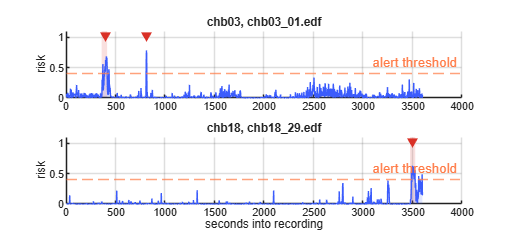

showRecs = {'chb03', 'chb03_01.edf'; 'chb18', 'chb18_29.edf'};
blue = [0.23 0.36 0.99];  red = [0.85 0.19 0.15];  orange = [1 0.48 0.27];
figure('Position', [100 100 1100 520]);
tiledlayout(size(showRecs, 1), 1, 'TileSpacing', 'compact');
for i = 1:size(showRecs, 1)
    id = showRecs{i, 1};  fn = string(showRecs{i, 2});
    m = Fs.(id).fileName == fn;
    t = Fs.(id).windowStartSec(m) + cfg.windowSec;
    r = Rk.(id)(m);
    nexttile;  hold on
    area(t, r, 'FaceColor', blue, 'FaceAlpha', 0.15, 'EdgeColor', blue);
    yline(cfg.alertThreshold, '--', 'alert threshold', 'Color', orange);
    sz = Ev.(id).seizures(Ev.(id).seizures.file == fn, :);
    for j = 1:height(sz)
        xregion(sz.onsetSec(j), sz.offsetSec(j), 'FaceColor', red, 'FaceAlpha', 0.15);
    end
    al = Ev.(id).alerts(Ev.(id).alerts.file == fn, :);
    plot(al.timeSec, 1.03 * ones(height(al), 1), 'v', 'Color', red, 'MarkerFaceColor', red);
    ylim([0 1.1]);  ylabel('risk');  grid on
    title(sprintf('%s, %s', id, fn), 'Interpreter', 'none');
end
xlabel('seconds into recording');

## 11. Robustness: fewer channels and added noise

We re-ran the test patients with 18, 8 and 4 channels and with noise added at several levels (SNR in dB, lower is noisier). The model was trained on the same channels. The noise is band-limited to 0.5 to 40 Hz at a fixed level relative to each patient's typical signal power. The threshold stays at 0.4.

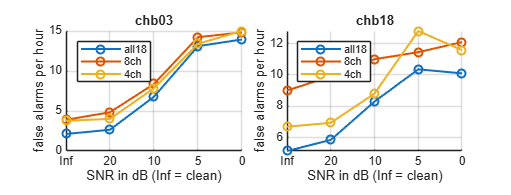

if rerunRobustness
    R03 = runRobustness(cfg.trainPatients, 'chb03', true);
    R18 = runRobustness(cfg.trainPatients, 'chb18', true);
else
    S = load(fullfile(cfg.dataRoot, 'models', 'final_robustness.mat'));
    R03 = S.R03;  R18 = S.R18;
end
rob = {R03, R18};
figure('Position', [100 100 1100 420]);
tiledlayout(1, 2, 'TileSpacing', 'compact');
for i = 1:2
    R = rob{i};
    nexttile;  hold on
    sets = unique(R.channelSet, 'stable');
    snr = unique(R.snrDb, 'stable');
    for s = 1:numel(sets)
        rr = R(R.channelSet == sets(s), :);
        plot(1:numel(snr), rr.falseAlarmsPerHour, '-o', 'LineWidth', 1.5, ...
             'DisplayName', char(sets(s)));
    end
    xticks(1:numel(snr));  xticklabels(string(snr));
    xlabel('SNR in dB (Inf = clean)');  ylabel('false alarms per hour');
    title(ids{i});  legend('Location', 'northwest');  grid on
end

% Sensitivity stayed at the clean level in almost every condition (table below).
% The cost of noise and fewer channels shows up as more false alarms.
varNames = {'channelSet', 'snrDb', 'auc', 'sensitivity', 'falseAlarmsPerHour', 'medianLatencySec'};
disp(R03(:, varNames))

    channelSet    snrDb      auc      sensitivity    falseAlarmsPerHour    medianLatencySec
    __________    _____    _______    ___________    __________________    ________________

     "all18"       Inf     0.98442         1               2.1325                  25      
     "all18"        20     0.98469         1               2.6656                  25      
     "all18"        10     0.98366         1                6.812                12.5      
     "all18"         5     0.97662         1                13.15                  10      
     "all18"         0     0.96908         1               13.979                  15      
     "8ch"         Inf     0.96216         1               3.9095                32.5      
     "8ch"          20     0.96263         1               

disp(R18(:, varNames))

    channelSet    snrDb      auc      sensitivity    falseAlarmsPerHour    medianLatencySec
    __________    _____    _______    ___________    __________________    ________________

     "all18"       Inf     0.92733      0.83333            5.1475                  15      
     "all18"        20     0.92906      0.83333            5.8552                  15      
     "all18"        10     0.93333      0.83333            8.3003                12.5      
     "all18"         5     0.92467      0.83333            10.359                  10      
     "all18"         0     0.90643      0.83333            10.102                17.5      
     "8ch"         Inf     0.93055      0.83333             9.008                  15      
     "8ch"          20     0.93039      0.83333            

## 12. A new, unannotated recording

This is the path a clinic would use: an EDF file with no annotations goes in, and a list of alerts to review comes out. Here we run chb03_01.edf through scoreRecording as if it were new (the function never reads the annotations).

Reading chb03_01.edf ...


  1439 windows (60.0 min)

=== chb03_demo: 1.00 hours analysed, threshold 0.40 ===
2 alerts (2.00 per hour). Review each one on the raw EEG.
         file         alertTimeSec    alertTimeHMS    meanRisk    peakRisk
    ______________    ____________    ____________    ________    ________

    "chb03_01.edf"        390          "00:06:30"     0.44839     0.59713 
    "chb03_01.edf"        815          "00:13:35"     0.70632     0.76674 

Screening aid only: a clinician must confirm every alert.


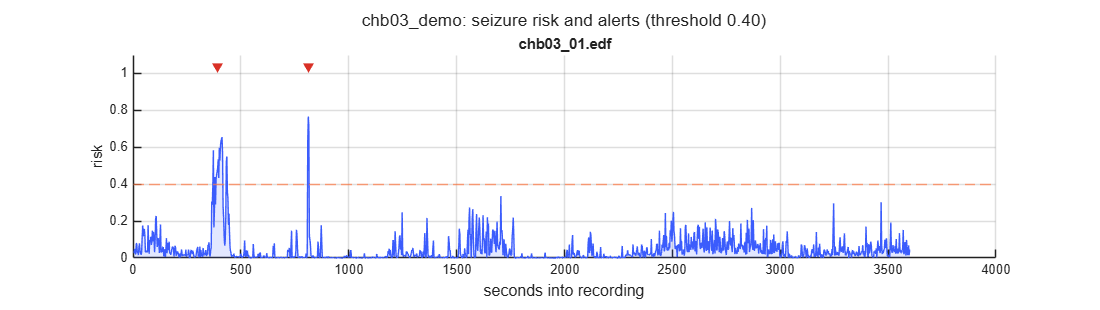

         file         alertTimeSec    alertTimeHMS    meanRisk    peakRisk
    ______________    ____________    ____________    ________    ________

    "chb03_01.edf"        390          "00:06:30"     0.44839     0.59713 
    "chb03_01.edf"        815          "00:13:35"     0.70632     0.76674 



edf = fullfile(cfg.rawDir, 'chb03', 'chb03_01.edf');
if isfile(edf)
    Rnew = scoreRecording(edf, 'Name', 'chb03_demo', 'Plot', true);
    disp(Rnew.alerts)
else
    disp('Raw EDF file not found on this computer: skipping the live demo.');
end

% The first alert is the annotated seizure (360 to 415 s) and the second is the false alert.

## 13. Dashboard

AtlasDashboard replays a recording window by window: the EEG, the risk curve with the threshold, an ALERT status, the model's top features, a log that labels each alert as a detection or a false alarm, and the patient's results. Run it with:

Screenshots (shown if the images are in the Docs folder):

shots = {'dashboard_before.png', 'dashboard_alert.png', 'dashboard_false_alert.png'};
for i = 1:numel(shots)
    f = fullfile(cfg.projectRoot, 'Docs', shots{i});
    if isfile(f)
        figure;  imshow(f);  title(shots{i}, 'Interpreter', 'none');
    end
end

## 14. Limitations

- Only four training patients and two test patients (13 test seizures), so these results describe these patients, not epilepsy in general. - Detectability varies strongly between patients, and false alarm rates differed between the two test patients (2.2 and 5.0 per hour). Overall 3.5 per hour is above our target of about one per hour, because the threshold was chosen from two training patients. - Rescaling uses the patient's whole recording as the baseline, so a live system would need a short baseline period. It may also flatter the noise results. - The model needs the 18 standard channels. The 8- and 4-channel results come from models retrained on those channels, and are examples, not clinical montages. - Detection only: not a diagnosis, and not validated for clinical use.

## 15. Conclusion

A patient-rescaled Random Forest on simple EEG features detected 12 of 13 seizures in two patients it had never seen, a median of 25 seconds after onset, and kept detecting them with as few as 4 channels and with added noise. False alarms remain the main limit. The same pipeline scores new, unannotated recordings and shows them on a dashboard, as a screening aid that helps a clinician find the stretches of EEG that need review.

## 16. Reproducing this

Setup: MATLAB R2026b with the Signal Processing and Statistics and Machine Learning Toolboxes. Set ATLAS_DATA to the data folder, then run this script. The steps that produced the saved results are listed in the repository README (section 5). Data: Guttag, J. (2010). CHB-MIT Scalp EEG Database v1.0.0. PhysioNet. [https://doi.org/10.13026/C2K01R](https://doi.org/10.13026/C2K01R)